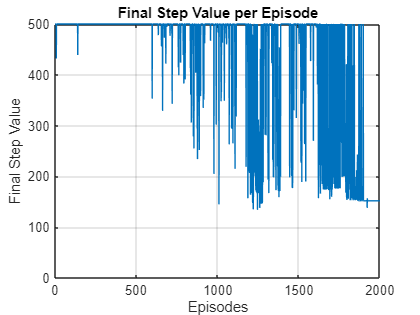

% Read data from results.csv
thisFile = matlab.desktop.editor.getActiveFilename;
thisFolder = fileparts(thisFile);
csvFile = fullfile(thisFolder, 'results.csv');
data = readmatrix(csvFile);


% Plot data:
x = 1:length(data);

% In this plot, the unsucessful episodes have a final step value of 500
plot(x, data);
xlabel('Episodes');
ylabel('Final Step Value');
title('Final Step Value per Episode');
ylim([0 500]);
grid on;

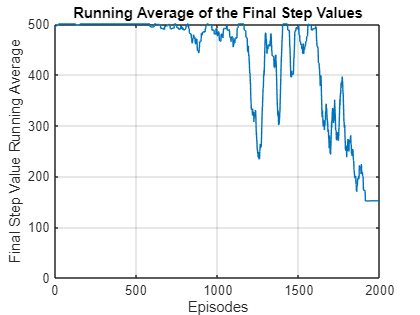


% This plot is a moving average version of the previous plot
windowSize = 25;   % number of points to average
dataAvg = movmean(data, windowSize);

plot(x, dataAvg);
xlabel('Episodes');
ylabel('Final Step Value Running Average');
title('Running Average of the Final Step Values');
ylim([0 500]);
grid on;